Load data file (struct 3D format) and get axes order

FolderPath = 'C:\Users\admin2\Documents\GitHub\mfiaDLTS\AcquireData\FrequencyAmplitudeBias_Sweep\vars';
FileName = 'B5 b5 150um 9 A_struct_3D_sweep_order_frequency_amplitude_offset';
Path = [FolderPath '\' FileName];
Data = load(Path)
Varname = fieldnames(Data);
Data = Data.(Varname{1});
StrBeforeOrder = 'order_'; % input the string just before the first parameter
Order = MFIA_get_order_from_path(Path, StrBeforeOrder)
title = Path(sum(find(Path=='\', 1, 'last'))+1:sum(strfind(Path, '_struct'))-1)

Select data to plot (leave empty to plot all data in 3D struct) and define plot aliases (from IA parametric model)

plt_select_data = {};
plt_select_data(:,end+1) = {'param0'; 'Resistance [ohm]'};
plt_select_data(:,end+1) = {'param1'; 'Capacitance [F]'};

Select plot range

range = {};
range(:,end+1) = {'frequency'; [0 inf]};
range(:,end+1) = {'amplitude'; [0 inf]}; 
range(:,end+1) = {'offset'; [-inf inf]};

Define slice planes

slice_planes = {};
slice_planes(:,end+1) = {'frequency'; [1e2 1e3 1e4 1e5 5e5]};
slice_planes(:,end+1) = {'amplitude'; []}; 
slice_planes(:,end+1) = {'offset'; [0 -0.1 -0.2 -0.5 -1]};

Add plot formatting commands:

all: plt_cmds(2,end+1) =  {'comand'}; '' for ' inside string.

target: plt_cmds(:,end+1) =  {'target' ; 'comand'};

plt_cmds = {};
% plt_cmds(2,end+1) = {'grid on'};
plt_cmds(2,end+1) = {'colorbar(''eastoutside'')'};
plt_cmds(2,end+1) = {'colormap(s,''turbo'')'};
plt_cmds(2,end+1) = {'colormap(s,interp1(colormap(s), 1:(length(colormap(s))/998):length(colormap(s))))'};
plt_cmds(:,end+1) = {'param0'; 'colormap(s,[compress_array_exp(colormap(s),10,10, ''Reverse'', true, ''Interp'', true)])'};
plt_cmds(2,end+1) = {'colormap(s,[0 0 0; colormap(s)])'};
% plt_cmds(2,end+1) = {'colormap([colormap; 1 1 1])'};
plt_cmds(:,end+1) = {'param0'; 'caxis([0 1e6])'};
plt_cmds(:,end+1) = {'param1'; 'caxis([0 inf])'};

plt_log_freq = true; % true for log plot frequency
if plt_log_freq
    Order{contains(Order, 'frequency')} = 'log_frequency';
    range(:,contains(range(1,:), 'frequency')) = {'log_frequency'; log10(range{2,contains(range(1,:), 'frequency')})};
    slice_planes(:,contains(slice_planes(1,:), 'frequency')) = {'log_frequency'; log10(slice_planes{2,contains(slice_planes(1,:), 'frequency')})};
end

Plot slice planes of 3D data

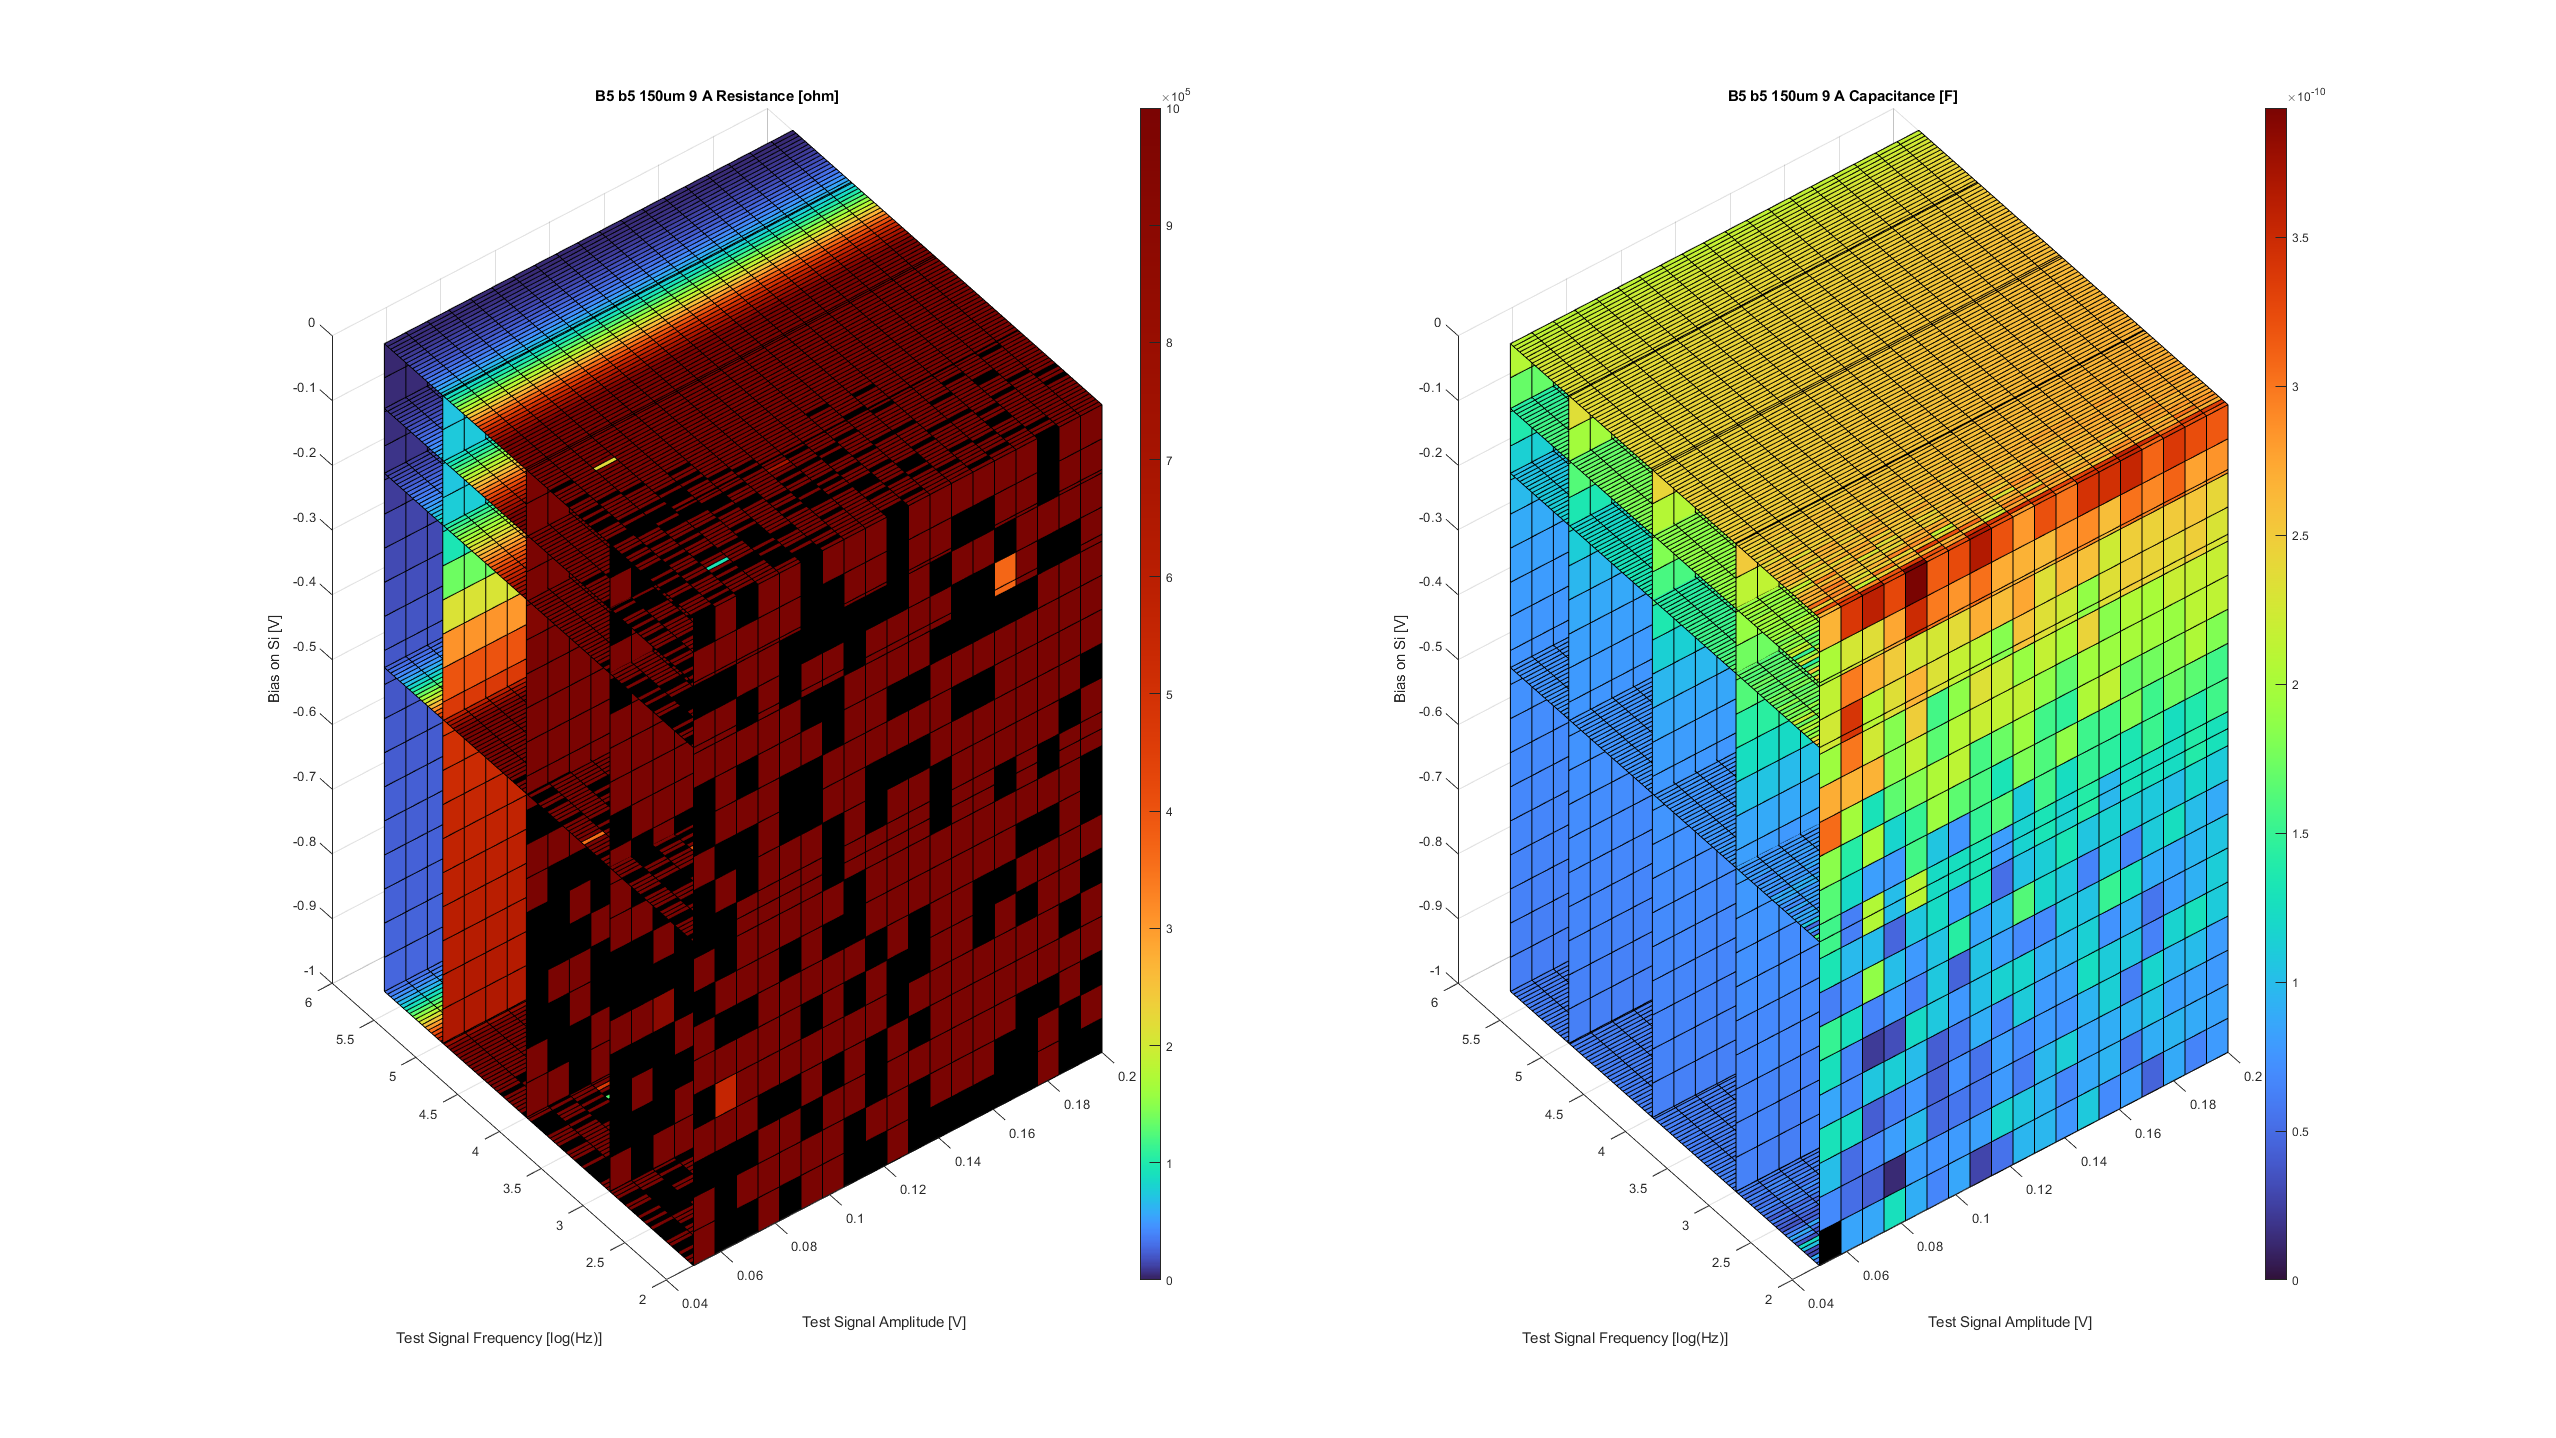

[fig1, sbp1, data_cell, axes_cell] = process_plot_struct_data3D(Data, Order, slice_planes, 'title', title, 'range', range, 'plt_select_data', plt_select_data, 'plt_cmds', plt_cmds);

SavePlotPathFileName = [FolderPath '\' title '\' FileName '_slice_plot'];
SaveFormat = {'fig', 'png'};
% save_plot(fig1, SavePlotPathFileName, SaveFormat)

**Fit data along a certain dimension**

C-V fit

CV_plot_fit = [];
CV_plot_fit.func = @plot;
CV_plot_fit.savepath = FolderPath;
CV_plot_fit = [];

CV_fit_select = {'capacitance'};
CV_fit_axis = 'offset';

syms V N Vb n
limits_A = {'Vb',[0 0.5 1],'N',[1e17 2e18 5e18],'n',[1 9 10]};
IdealityFactor = 1;
es = 11.68;
A = (150^2 * pi)*1e-8;
CV_range = [-inf inf];
CV_fit_func = @(x,y) C_schot_fit_A(x,y,CV_range,A,es,N,Vb,IdealityFactor);

[fig2, sbp2, FitSavePath, FitName] = fit_cell_3D(data_cell, axes_cell, CV_fit_func, CV_fit_axis, 'plt_select_data',CV_fit_select, 'title',title, 'plot_fit',CV_plot_fit);
saveas(fig2, [FitSavePath '\' FitName '.fig']);
saveas(fig2, [FitSavePath '\' FitName '.png']);

DLCP fit

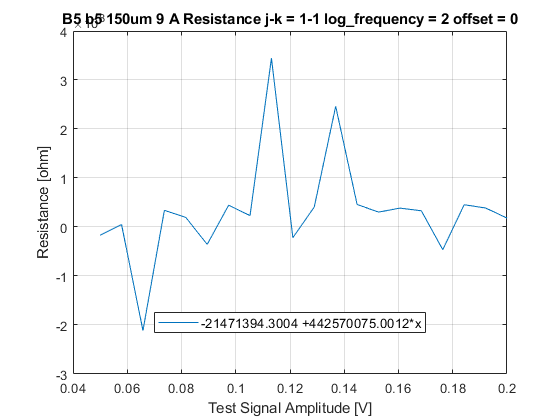

DLCP_plot_fit = [];
DLCP_plot_fit.func = @plot;
% DLCP_plot_fit.savepath = FolderPath;
% DLCP_plot_fit = [];

DLCP_fit_select = {'capacitance'};  
DLCP_fit_axis = 'amplitude';

MaxPower = 1;
DLCP_params = {'C0', 'C1'};
DLCP_amplitude_Range = [-inf inf];
DLCP_fit_func = @(x,y) str_poly_fit(x,y,MaxPower, 'params',DLCP_params, 'range',DLCP_amplitude_Range);

[fig3, sbp3, FitSavePath, FitName] = fit_cell_3D(data_cell, axes_cell, DLCP_fit_func, DLCP_fit_axis, 'plt_select_data',DLCP_fit_axis, 'title',title, 'plot_fit',DLCP_plot_fit);

saveas(fig3, [FitSavePath '\' FitName '.fig']);
saveas(fig3, [FitSavePath '\' FitName '.png']);